% lab14_ex_speech_compress.m
% Speech compression using linear prediction coding
clear all; close all;
warning('off')

ifigs = 1;             %  0/1 - to show figures inside the processing loop?

% Parameters
Mlen=256;              % length of analyzed block of samples
Mstep=180;             % offset between analyzed data blocks (in samples)
Np=2;                  % prediction order (IIR-AR filter order)
where=181;             % initial position of the first voiced excitation
roffset=20;            % offset in auto-correlation function when find max
compress=[0 0 0 0 0];           % table for calculated speech model coefficients
s=[];                  % the whole synthesized speech
ss=[];                 % one fragment of synthesized speech

% Read signal to compress
[x,fs]=audioread('mowa1.wav');	   % read speech signal (audio/wav/read)
figure; plot(x); title('Speech');  % display it
% soundsc(x,fs); pause               % play it on loudspeakers (headphones)
N=length(x);                       % signal length
bs=zeros(1,Np);			   % synthesis filter buffer
Nblocks=floor((N-Mlen)/Mstep+1);   % number of speech blocks to be analyzed

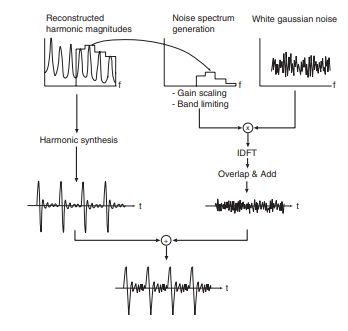

for  nr = 1 : Nblocks
    n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
    bx = x(n);
    % ANALYSIS - calculate speech model parameters
    bx = bx - mean(bx);
    
    for k = 0 : Mlen-1
        r(k+1)=sum( bx(1:Mlen-k) .* bx(1+k:Mlen) ); % calculate auto-correlation
    end
    % try: r=xcorr(x,'unbiased')
    if(ifigs==1)
        subplot(411); plot(n,bx); title('Input speech x(n)');
        subplot(412); plot(r); title('Its auto-correlation rxx(k)');
    end
    [rmax,imax] = max( r(roffset : Mlen)  );        % find max of auto-correlation
    imax = imax+(roffset-1);                        % its argument (position)
    if ( rmax > 0.35*r(1) )  T=imax; else T=0; end  % is the speech periodic?
    if (T>80) T=round(T/2); end                     % second sub-harmonic found
    
    rr(1:Np,1)=(r(2:Np+1))';                    % create an auto-correlation vector
    
    for m=1:Np                                  %
        R(m,1:Np)=[r(m:-1:2) r(1:Np-(m-1))];	 % build an auto-correlation matrix
    end                                         % a = lpc(x,Np), levinson(x,Np)
    
    a=-inv(R)*rr;                               % find coeffs of LPC filter
    %a = lpc(bx,Np);
    gain=r(1)+r(2:Np+1)*a;                      % find filter gain
    
    [H, WD]=freqz(1,[1;a],256);                     % find filter frequency response
    [revH, WH ] = freqz([1;a], 1,256);
    
    % odpowiedz filtra H
    %if(ifigs==1)
    %    figure
    %    stem(H(1:10:end))
    %end
    
    % resztkowy filtered
    bxfd = filter(revH, 1, bx);%[bx; zeros(128,1)]);
    
    % filter plots
    if(ifigs==1)
        figure
        plot(WH, 20*log10(abs(revH)), '-', WD, 20*log10(abs(H)), '--')
        legend({'reversed', 'normal'})
    end
    
    % widmo
    w = abs(fft(bxfd));
    
    % filtr wygladzania
    wygH1 = fir1(256,0.5,'low',blackman(256+1));
    [wygH, wygF] = freqz(wygH1,1,128);
    
    % wygladzanie
    uprBXfd = filter(wygH, 1, bxfd);
    
    % freq plot resp reszkowego dla przed wygladzaniem i po
    if(ifigs==1)
        figure; plot(wygF, 20*log10(abs(wygH)))
        
        figure; plot(w, 'b');
        hold on; plot(abs(fft(uprBXfd)), 'r');
        legend({'przed', 'po'})
        %xlim([0 50])
    end
    
    % niepotrzebne teraz
    if(ifigs==1) subplot(413); plot(abs(H)); title('Filter freq response'); end
    if(ifigs==1) subplot(413); plot(abs(revH)); title('Reversed filter freq response'); end
    
    % rekonstrukcja z widma
    if (T~=0)
        where=where-Mstep;
         
    end            % next excitation=1 position
    if( T==0)
        for n=1:Mstep                               % SYNTHESIS LOOP START
            %
            % exc=2*(rand(1,1)-0.5); where=271;   % random excitation
            exc=0.5*randn(1,1); where=271;      % random excitation
            %
            ss(n) = gain*exc - bs*a;                % filtering excitation
            bs = [ss(n) bs(1:Np-1) ];               % shifting the output buffer      
        end                                         % SYNTHESIS LOOP END
    end
end